### Testing shape generation

length_x = 5;
length_y = 1;
posn_rect = [1; 3];
theta = pi/6; % Rads
resolution = 64; % Total points (distributed evenly)
points_rect = generate_rect(length_x, length_y, posn_rect, theta, resolution);

radius = 2;
posn_circle = [-1; -3];

points_circle = generate_circle(radius, posn_circle, resolution);

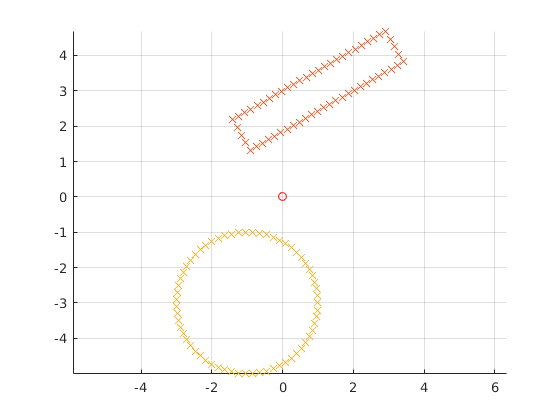

figure();
hold on

plot(0, 0, 'ro')

scatter(points_rect(1, :), points_rect(2, :), 'x')
scatter(points_circle(1, :), points_circle(2, :), 'x')

grid on
axis equal

### Constructing the gauntlet

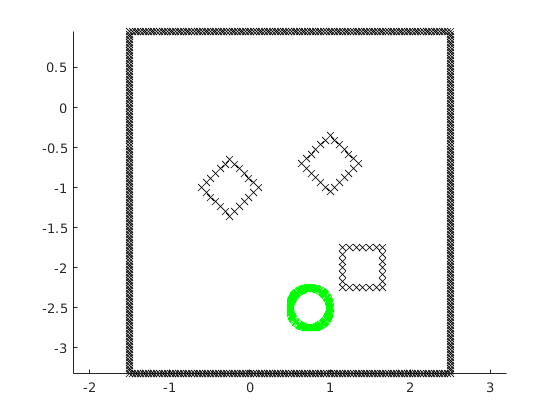

border_res = 500;
obs_res = 30;
bucket_res = 300;


border = generate_rect(4, 4.27, [0.5; -1.185], 0, border_res);
cube_1 = generate_rect(0.5, 0.5, [-0.25; -1], pi/4, obs_res);
cube_2 = generate_rect(0.5, 0.5, [1; -0.7], pi/4, obs_res);
cube_3 = generate_rect(0.5, 0.5, [1.41; -2], 0, obs_res);
sources = [border, cube_1, cube_2, cube_3];

bucket = generate_circle(0.25, [0.75; -2.5], bucket_res);
sinks = bucket;

figure()
hold on
plot(sources(1,:), sources(2,:),'xk')
plot(sinks(1,:), sinks(2,:), 'xg')
axis equal

### Create Potential Field and Gradient Functions

f_potential_sink = @(X, Y, a, b) (log(sqrt((X-a).^2 + (Y-b).^2)));
f_grad_sink = @(X, Y, a, b) (deal( ...
    -(X-a)./((X-a).^2 + (Y-b).^2), ...
    -(Y-b)./((X-a).^2 + (Y-b).^2)...
));

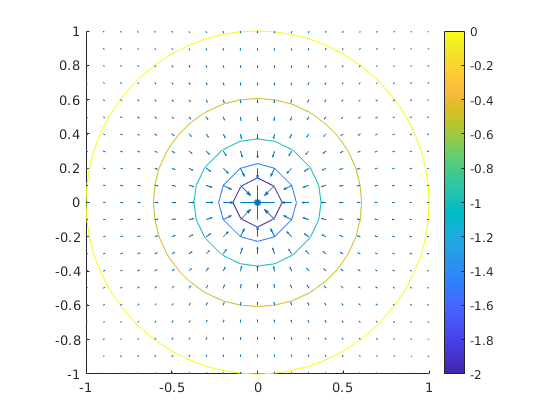

[X, Y] = meshgrid(-1:0.1:1, -1:0.1:1);

a = 0;
b = 0;

Z = f_potential_sink(X, Y, a, b);
[U, V] = f_grad_sink(X, Y, a, b);

figure()
hold on;

contour(X, Y, Z);
quiver(X, Y, U, V);
colorbar

axis equal

### Create Potential Field and Gradient for the Gauntlet

res = 1000;
x = linspace(-2, 3, res);
y = linspace(-3.5, 1.5, res);
[X, Y] = meshgrid(x, y);


[Z_sources, U_sources, V_sources] = calculate_fields(X, Y, sources, -1); % -1 to indicate these are sources

[Z_sinks, U_sinks, V_sinks] = calculate_fields(X, Y, sinks, 1);

Z = Z_sources+Z_sinks;
U = U_sources+U_sinks;
V = V_sources+V_sinks;

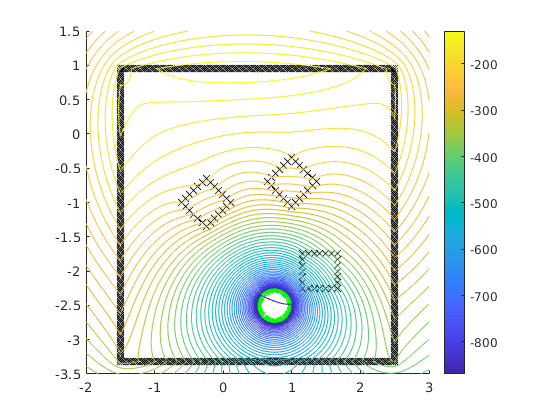

figure()
hold on;    

plot(sources(1,:), sources(2,:),'xk')
plot(sinks(1,:), sinks(2,:), 'xg')
    
contour(X, Y, Z, 50);
colorbar

axis equal

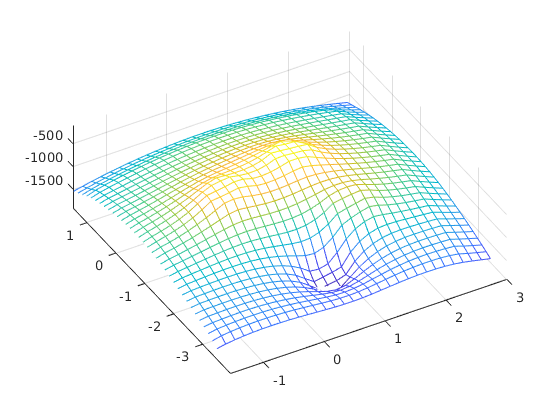

figure()
n = 30;
selection = 1:n:length(X);
mesh(X(selection, selection), Y(selection, selection), Z(selection, selection))

function points_out = generate_rect(length_x, length_y, position, theta, resolution)
    % Create rect points
    res_x = 0.5 * resolution * length_x / (length_x + length_y);
    res_y = 0.5 * resolution * length_y / (length_x + length_y);
    
    edge_coords_x = length_x * linspace(-0.5, 0.5, res_x);
    edge_coords_y = length_y * linspace(-0.5, 0.5, res_y);
    const_coords_x = length_x * 0.5*ones(size(edge_coords_y));
    const_coords_y = length_y * 0.5*ones(size(edge_coords_x));
    
    
    top_edge = [edge_coords_x; const_coords_y];
    bottom_edge = [edge_coords_x; -const_coords_y];
    
    left_edge = [-const_coords_x; edge_coords_y];
    right_edge = [const_coords_x; edge_coords_y];
    
    points_out = [top_edge, bottom_edge, left_edge, right_edge];
    
    % Rotate rect about center
    rot_mat = [cos(theta) -sin(theta);
               sin(theta)  cos(theta)];
    
    points_out = rot_mat*points_out;
    
    % Translate rect
    points_out = [points_out; ones(1, size(points_out, 2))];
    trans_mat = eye(3);
    trans_mat(1:2, 3) = position;
    
    points_out = trans_mat*points_out;
end

function points_out = generate_circle(radius, position, resolution)
    thetas = linspace(0, 2*pi, resolution);
    
    % Create circle points
    points_out = [radius*cos(thetas);
              radius*sin(thetas);
              ones(size(thetas))];
    
    % Translate circle
    trans_mat = eye(3);
    trans_mat(1:2, 3) = position;
    
    points_out = trans_mat*points_out;
end

function Z = potential_sink(X, Y, a, b)
    Z = log(sqrt((X-a).^2 + (Y-b).^2));
end

function [U, V] = grad_sink(X, Y, a, b)
    U = -(X-a)./((X-a).^2 + (Y-b).^2);
    V = -(Y-b)./((X-a).^2 + (Y-b).^2);
end

function [Z, U, V] = calculate_fields(X, Y, points, coeff)
    Z = zeros(size(X));
    U = zeros(size(X));
    V = zeros(size(X));
    
    for i = 1 : size(points, 2)
        a = points(1, i);
        b = points(2, i);
        
        Z = Z + coeff*potential_sink(X, Y, a, b);
        [U_i, V_i] = grad_sink(X, Y, a, b);
        
        U = U + coeff*U_i;
        V = V + coeff*V_i;
    end
end